# Exercise 5. Morphological operations: Erosion, dilation, openings and closings

E5ADSB, Sep. 2020, Janus

clear all; close all; clc;

## Part 1: Erosion

### 01 Binary image and structuring element

I = [0 0 0 0 0 0 0 0;
     0 1 1 1 1 1 0 0;
     0 1 1 1 1 1 0 0;
     0 0 1 1 1 1 0 0;
     0 0 1 1 1 1 0 0;
     0 0 0 0 0 0 0 0;];

SE = [0 1 0;
      1 1 1;
      0 1 0];

### 02 Erode the binary image with the SE

Use the SE, consisting of a 4-nbor cross

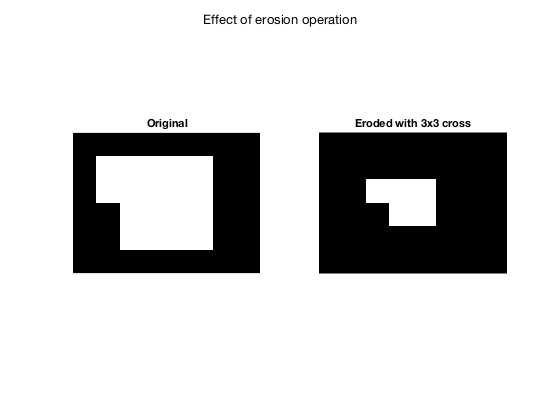

Ie = imerode(I, SE);
figure;
subplot(121)
imshow(I)
title('Original')
subplot(122)
imshow(Ie)
title('Eroded with 3x3 cross')
sgtitle('Effect of erosion operation')

Notice how erosion "takes away" from the image. It shrinks large parts, and removes small parts.

### 03 Erosion with 3x3 square SE

Erode with a 3x3 square instead

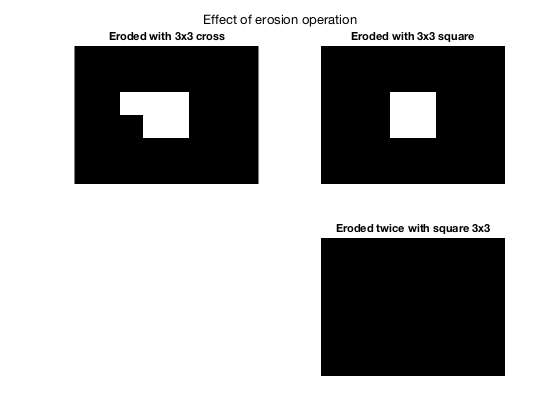

SE3 = ones([3 3]);
Ie3 = imerode(I, SE3);
figure;
subplot(221)
imshow(Ie)
title('Eroded with 3x3 cross')
subplot(222)
imshow(Ie3)
title('Eroded with 3x3 square')
subplot(224)
imshow(imerode(Ie3, SE3))
title('Eroded twice with square 3x3')
sgtitle('Effect of erosion operation')

The figure shows how the erosion operation takes away "thin" parts and shrinks objects. Thin is relative to the half width of the SE.

### 04 Load the binary image “wirebond-mask.tif” and show it.

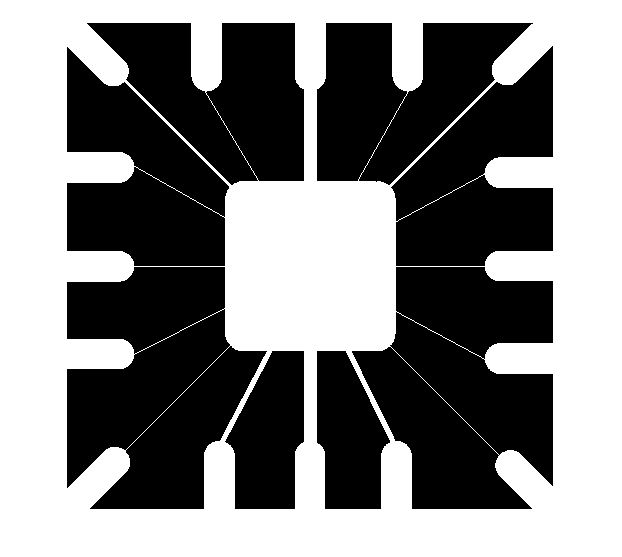

wbm = imread('img/wirebond-mask.tif');
figure; imshow(wbm)

### 05-06 Create square structuring element of size 11x11, or higher

This can remove thin lines, will leave thicker lines visible.

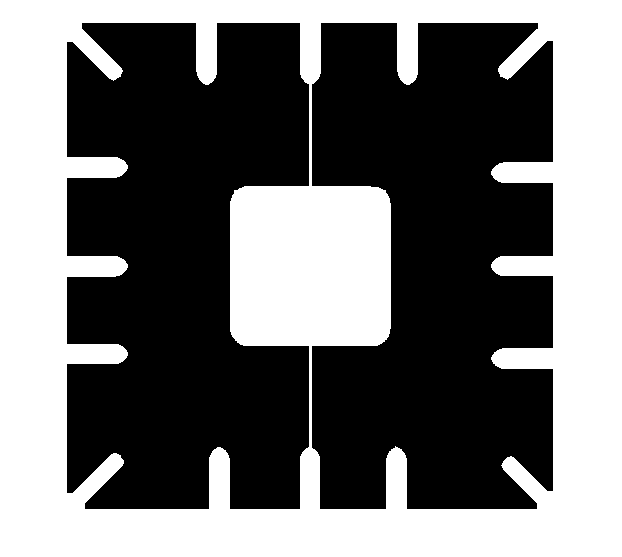

SE11 = strel('square', 11);
Ie11 = imerode(wbm, SE11);
figure; imshow(Ie11)

These larger SEs take away all "small" and "thin" elements, relatively speaking. This means that more of the fine detail on the binary image is eroded as the SE gets larger.

## Part 2. Dilation

clear all; close all; clc;

01 Binary image and structuring element

I = zeros([6 6]);
I(4:5,3:4) = 1;
%figure; imshow(I);

SE = [0 1 0;
      1 1 1;
      0 1 0];
  

### 02 Dilate the image

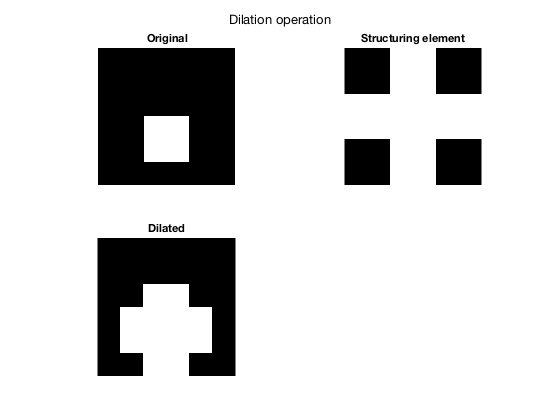

Ie = imdilate(I, SE);
figure; 
subplot(221)
imshow(I)
title('Original')

subplot(222)
imshow(SE)
title('Structuring element')

subplot(223)
imshow(Ie)
title('Dilated')
sgtitle('Dilation operation')

Note how dilation “grow” or “thickens” the object in the image.

#### Now, use dilation to fix an apparently broken (dithered?) image

clc; clear all; close all;

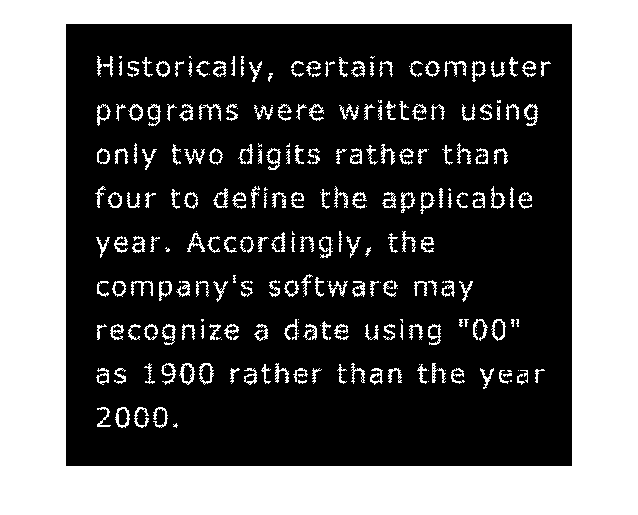

I = imread('img/text_gaps_1_and_2_pixels.tif');
figure; imshow(I)

This image could be the result of a bad scanning process, lossy compression or bad quantization.

Attempt to fix it using the 3x3 cross SE, and other SEs

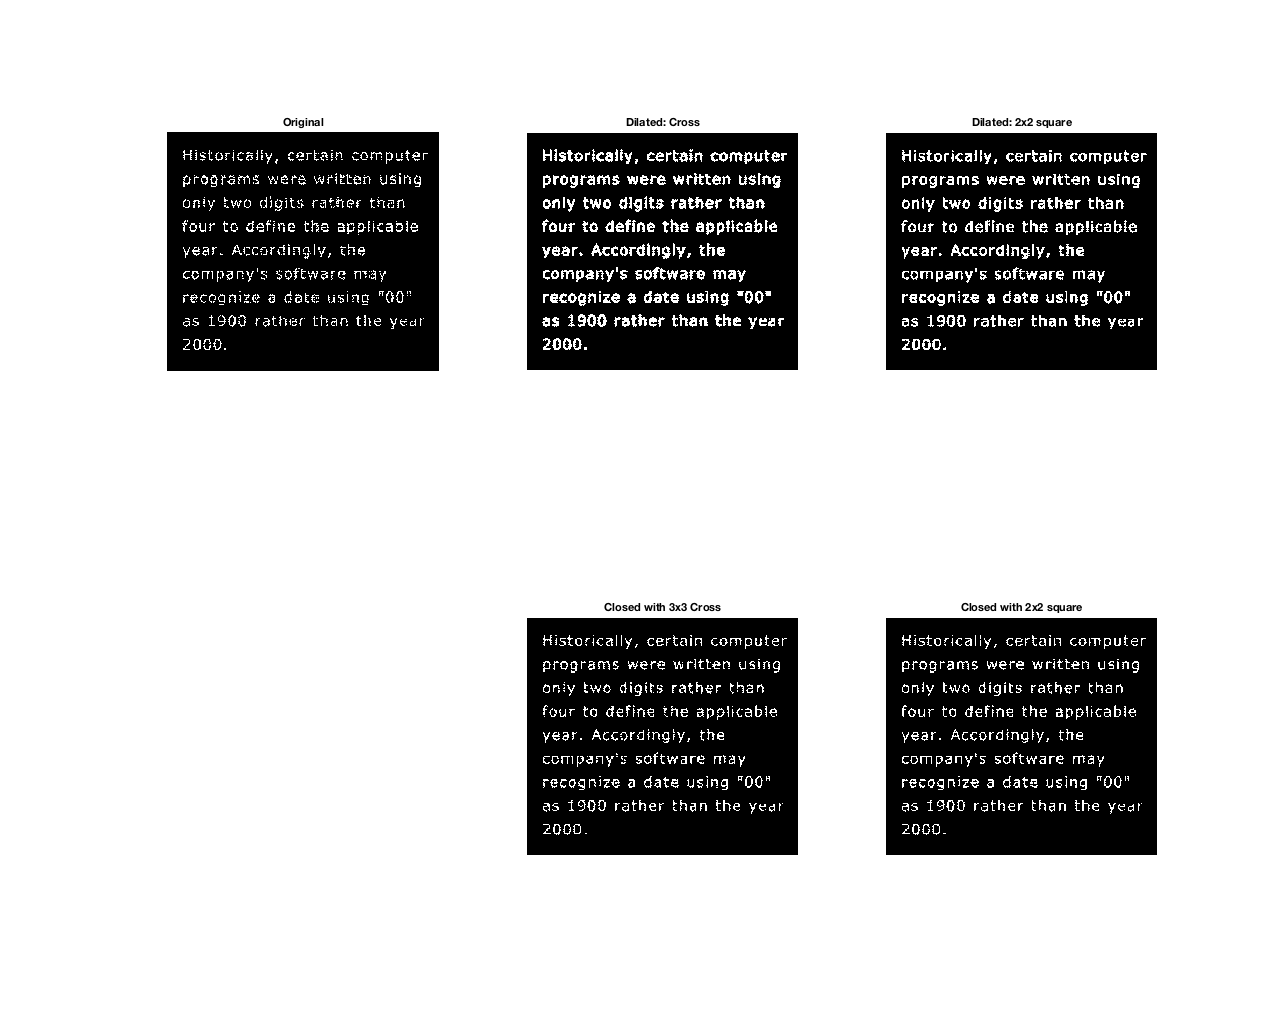

SE_cr = [0 1 0;
         1 1 1;
         0 1 0];       % Cross SE

SE_sq = ones(2);       % Square SE

figure;
set(gcf,'position',[0 0 1280 1024])
subplot(231)
imshow(I)
title('Original')

subplot(232)
imshow(imdilate(I, SE_cr))
title('Dilated: Cross')

subplot(233)
imshow(imdilate(I, SE_sq))
title('Dilated: 2x2 square')

subplot(235)
imshow(imclose(I, SE_cr))
title('Closed with 3x3 Cross')

subplot(236)
imshow(imclose(I, SE_sq))
title('Closed with 2x2 square')

Gaps can be filled in using dilation or closing. The image closed with 2x2 square appears more legible than the others.

## Part 3. Opening

Opening of the image $A$ by the structuring element $B$ is defined as the composite operation: $\left(A\ominus B\right)\oplus B$.

I.e. first, erosion (removes noise), and the dilation (replaces lost mass).

clc; close all; clear all;
I = imread('img/opening_testimage1.tif');

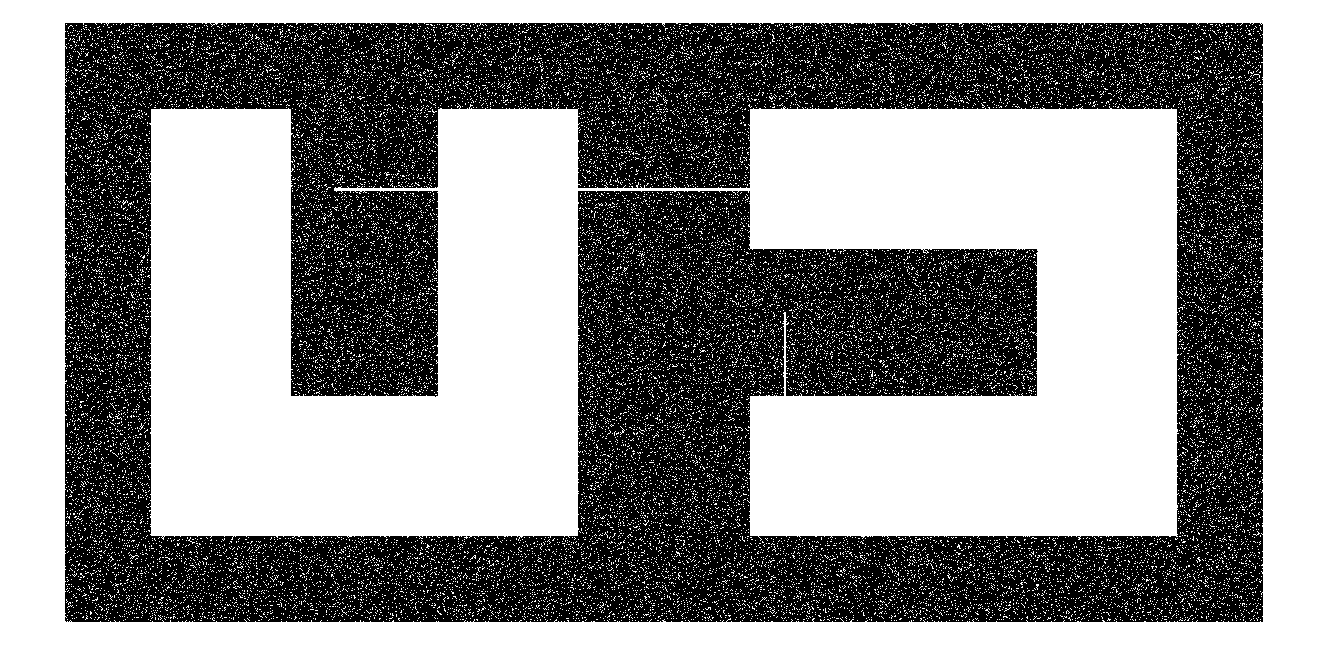

figure; imshow(I)

The image is noisy, and due to artefacts, the two elements are connected and technically count as one.

Use a square SE to 'open' the image

The height of the horizontal artefact is 3 pixels plus random noise (inspect it with imtool to verify).

So to be sure that the artefact is removed, use a square SE with dim 5x5. Anything smaller than the SE will be removed initially by the erosion. The remaining part of the image set can be restored (approximately) to its original size by dilation.

Opening: $A\circ B=\left(A\ominus B\right)\oplus B$.

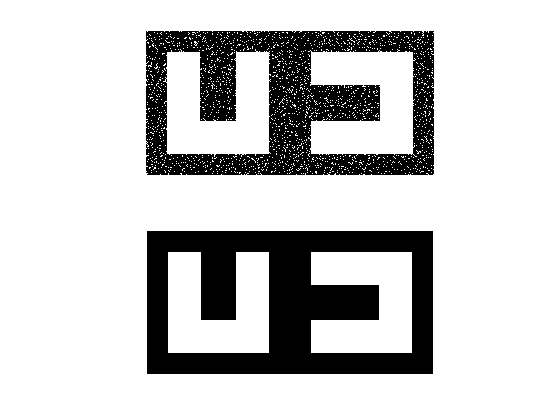

SE = strel('square', 5);
Iopen = imopen(I, SE);
figure;
subplot(211); imshow(I)
subplot(212); imshow(Iopen)

The opening operation succesfully removes noise and the artefact, leaving two separate objects in the image, which could then be segmented further.

Attemting the same with a circular SE

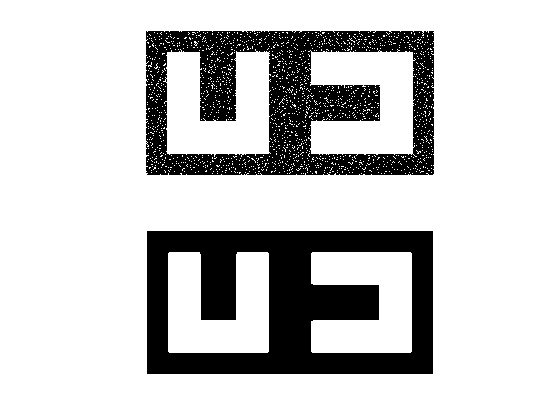

SE = strel('disk', 20);     % Radius 20
Iopen = imopen(I, SE);
figure;
subplot(211); imshow(I)
subplot(212); imshow(Iopen)

Choice of SE is important i relation to the image that needs to be recovered. E.g. using a disk will yield rounded corners where before were sharp corners.

## Part 4. Closing

Using the operation closing, closing the image $A$ by the SE $B$: $A\bullet B=\left(A\oplus B\right)\ominus B$.

clc; clear all; close all;

Another noise image with artefacts

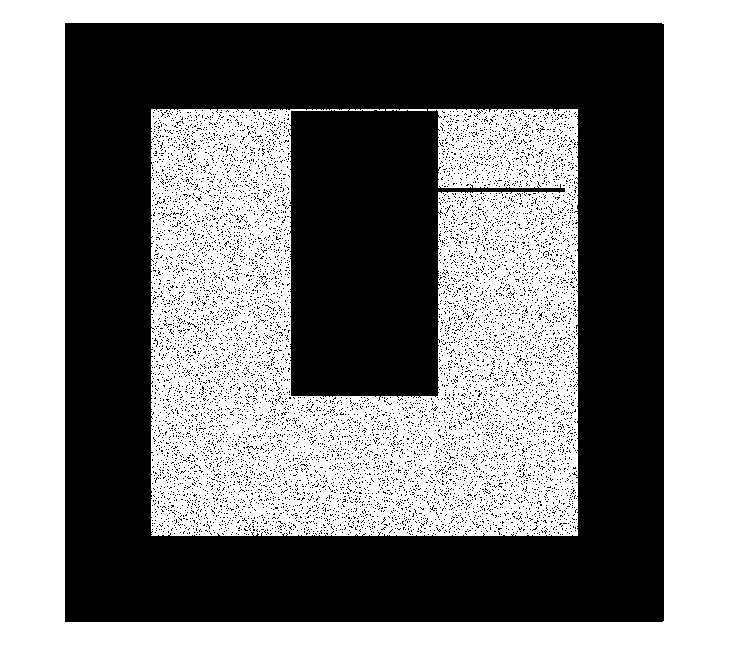

ift = imread('img/closing_testimage1.tif');
figure; imshow(ift)

The closing operation can fill in small gaps. Small is relative to the dimensions of the SE.

We want to recover a solid U-shape with a small overbar.

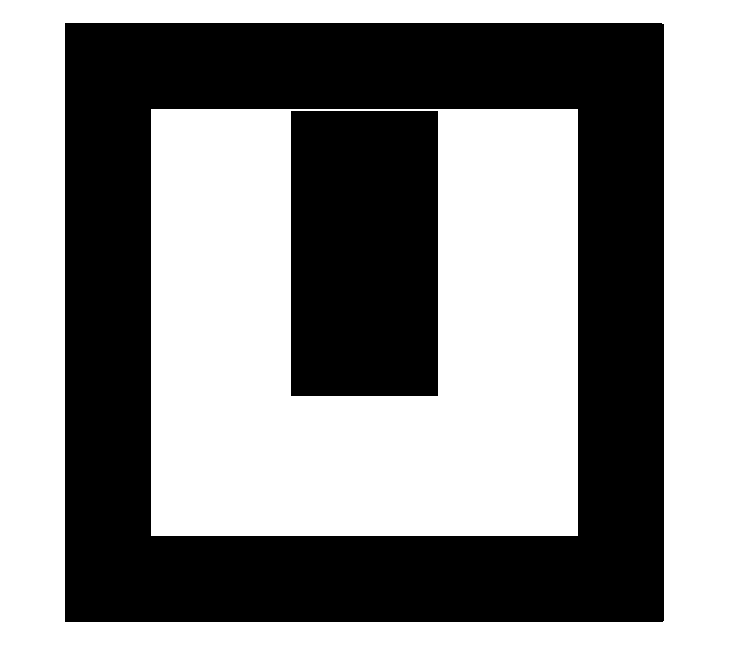

SE = strel('square', 5);
ift2 = imclose(ift, SE);
figure; 
imshow(ift2)

This leaves an image where all the small black gaps in the original shape have been filled in.

The overbar can be removed using opening:

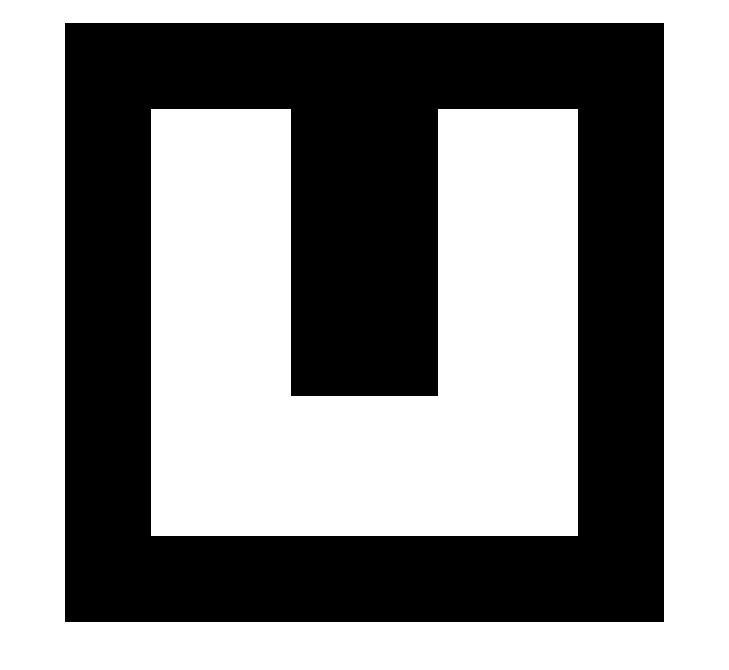

figure;
imshow(imopen(ift2,SE))

## Part 5. Morphological filtering

Opening followed by closing can reduce noise in a binary image

clc; close all; clear all;

Noisy fingerprint image

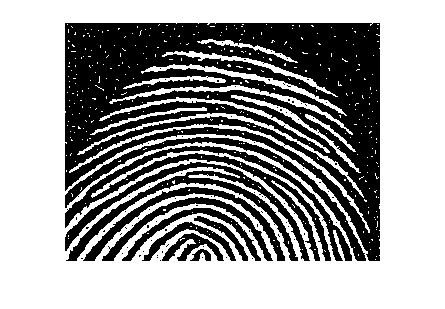

A = imread('img/noisy_fingerprint.tif');
figure; imshow(A);

Structuring element is a 3x3 square

B = ones(3);

Process:

- Erode image: $I_1 =A\ominus B$

- Dilate image: $I_2 =I_1 \oplus B=\left(A\ominus B\right)\oplus B=A\circ B$ (opening of A by B)

- Dilate the dilation: $I_3 =I_2 \oplus B=\left(A\circ B\right)\oplus B$ (dilation of opening)

- Erode the dilated dilation: $I_4 =I_3 \ominus B=\left(I_2 \oplus B\right)\ominus B=I_2 \bullet B=\left(A\circ B\right)\bullet B$ (closing of the opening)

I1 = imerode(A, B);
I2 = imdilate(I1, B);
I3 = imdilate(I2, B);
I4 = imerode(I3, B);

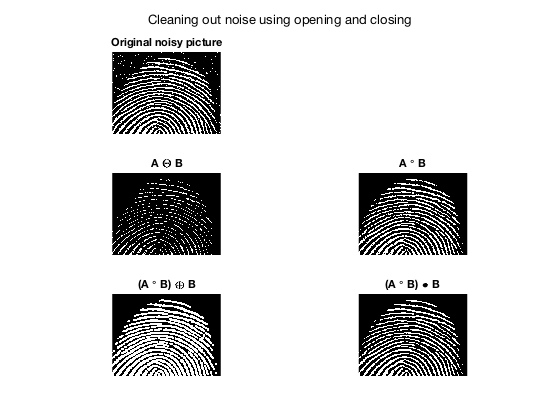

figure;
subplot(321)
imshow(A)
title('Original noisy picture')

subplot(323)
imshow(I1)
title('A \Theta B')

subplot(324)
imshow(I2)
title('A \circ B')

subplot(325)
imshow(I3)
title('(A \circ B) \oplus B')

subplot(326)
imshow(I4)

title('(A \circ B) \bullet B')

sgtitle('Cleaning out noise using opening and closing')

The final picture is cleared of noise and has well-shaped lines for further analysis.

## Part 6. Extraction and labelling of connected components

See Marques 13.6.3

clc; clear all; close all;

Algorithm:

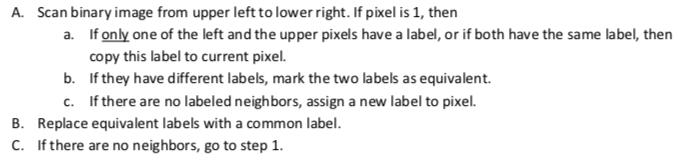

This is implemented as `bwlabel`.

Build a binary image that looks a bit like a QR code:

I = zeros([6 7]);
I(1,5:6)=1; I(2,2:4)=1; I(3,3:4)=1;
I(3:5,7)=1; I(5,5)=1; I(5:6,2:3)=1;

%doc bwlabel

I =      0     0     0     0     1     1     0
     0     1     1     1     0     0     0
     0     0     1     1     0     0     1
     0     0     0     0     0     0     1
     0     1     1     0     1     0     1
     0     1     1     0     0     0     0


labels =      0     0     0     0     3     3     0
     0     1     1     1     0     0     0
     0     0     1     1     0     0     5
     0     0     0     0     0     0     5
     0     2     2     0     4     0     5
     0     2     2     0     0     0     0


n = 5

`bwlabel(I, nbors)` returns a same-sized matrix as `I` with label numbers, for the `n`-neighbor connected components.

nbors = 4;      % look for 4-connected nbors
[labels, n] = bwlabel(I, nbors);
I, labels, n

The algorithm has found $n=5$ connected regions in the image, labelled $1,\dots ,5$.

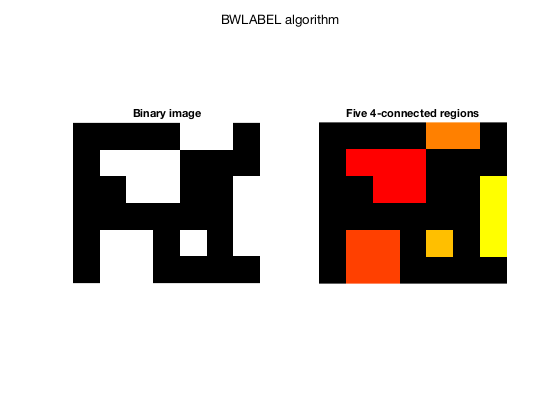

figure;
subplot(121)
imshow(I, []);
title('Binary image')
subplot(122)

imshow(label2rgb(labels, 'autumn', 'k'), []); % 0->black, other labels mapped to full RGB colorspace
title('Five 4-connected regions')
sgtitle('BWLABEL algorithm')

Note the two regions in the top, as we're only requiring 4-connection, there is no search for diagonal neighbours. So, the diagonally two adjacent regions are recognized as two distinct regions.

Attempt the same, but with 8-connection (also searching diagonally)

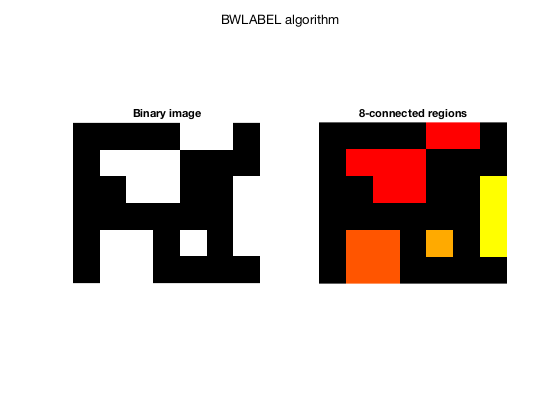

figure;
subplot(121)
imshow(I, []);
title('Binary image')
subplot(122)

imshow(label2rgb(bwlabel(I,8), 'autumn', 'k'), []); % 0->black, other labels mapped to full RGB colorspace
title('8-connected regions')
sgtitle('BWLABEL algorithm')

With 8-connection required (searching in all 8 neighbour pixels), the two diagonally adjacent regions in the top of the image are now recognized as one region.

## Fun

Playing around with an image with noise from high ISO

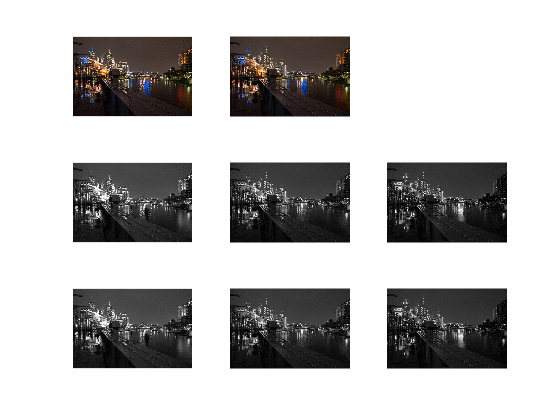

I = im2double(imread('img/noise-with-high-iso.jpg'));
SE = strel('square', 2);

I_new = I; % copy

IoR = imopen(I(:,:,1), SE);  % fix red channel
IoG = imopen(I(:,:,2), SE);  % fix green channel
IoB = imopen(I(:,:,3), SE);  % fix blue channel

I_new(:,:,1) = IoR; % replace red channel
I_new(:,:,2) = IoG; % replace green channel
I_new(:,:,3) = IoB; % replace blue channel

figure; 
subplot(331); imshow(I)
subplot(332); imshow(I_new)
subplot(334); imshow(I(:,:,1))   % R
subplot(335); imshow(I(:,:,2))   % G
subplot(336); imshow(I(:,:,3))   % B

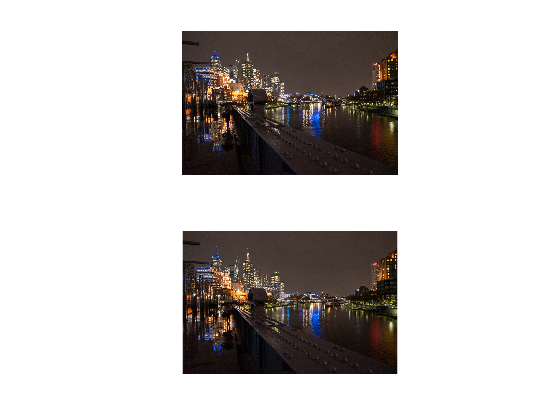

subplot(337); imshow(IoR)   % opened R
subplot(338); imshow(IoG)   % opened G
subplot(339); imshow(IoB)   % opened B
figure;
subplot(211)

imshow(I)
subplot(212)
imshow(I_new)